1 задание

sym x

$$ans = x$$

f = [1 4 -2 -14 -3 -18];
y = poly2sym(f,x);

factor(y)

$$ans = \left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

2 задание

sym x

$$ans = x$$

f = (tan(x))^tan(2*x);
limit(f,pi/4)

$$ans = {\mathrm{e}}^{-1}$$

3 задание

sym x

$$ans = x$$

f = (1/6)*log((x-3)/(x+3));
y = diff(f,x)

$$y = \frac{\left(\frac{1}{x+3}-\frac{x-3}{{\left(x+3\right)}^{2}}\right)\,\left(x+3\right)}{6\,\left(x-3\right)}$$

simplify(y)

$$ans = \frac{1}{x^{2}-9}$$

4 задание

sym x

$$ans = x$$

f = 1/(x^2-1)

$$f = \frac{1}{x^{2}-1}$$

int(f,-2,2)

$$ans = \mathrm{NaN}$$


f1 = 1/(sin(x))^3

$$f1 = \frac{1}{{\sin\left(x\right)}^{3}}$$

int(f)

$$ans = -\mathrm{atanh}\left(x\right)$$


f2 = 1/(x^2+1)

$$f2 = \frac{1}{x^{2}+1}$$

int(f2, 0, +inf)

$$ans = \frac{\pi }{2}$$

5 задание

syms x n k
symsum(((3-x)^(2*n))/((n)^(1/2)), n,1, inf)

$$ans = \sum_{n=1}^{\infty }\frac{{\left(x-3\right)}^{2\,n}}{\sqrt{n}}$$


symsum(1/((x-k)^3), k, -inf, +inf)

$$ans = \left\{ \begin{array}{cl} \frac{\psi^{\prime \prime }(-x)}{2}-\frac{1}{x^{3}}-\frac{\psi^{\prime \prime }(x)}{2} & \text{ if }x\notin \mathbb{Z} \end{array}\right.$$

6 задание

syms x 

y = exp(x)

$$y = {\mathrm{e}}^{x}$$

yapr = taylor(exp(x),'ExpansionPoint',0, 'Order',5)

$$yapr = \frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

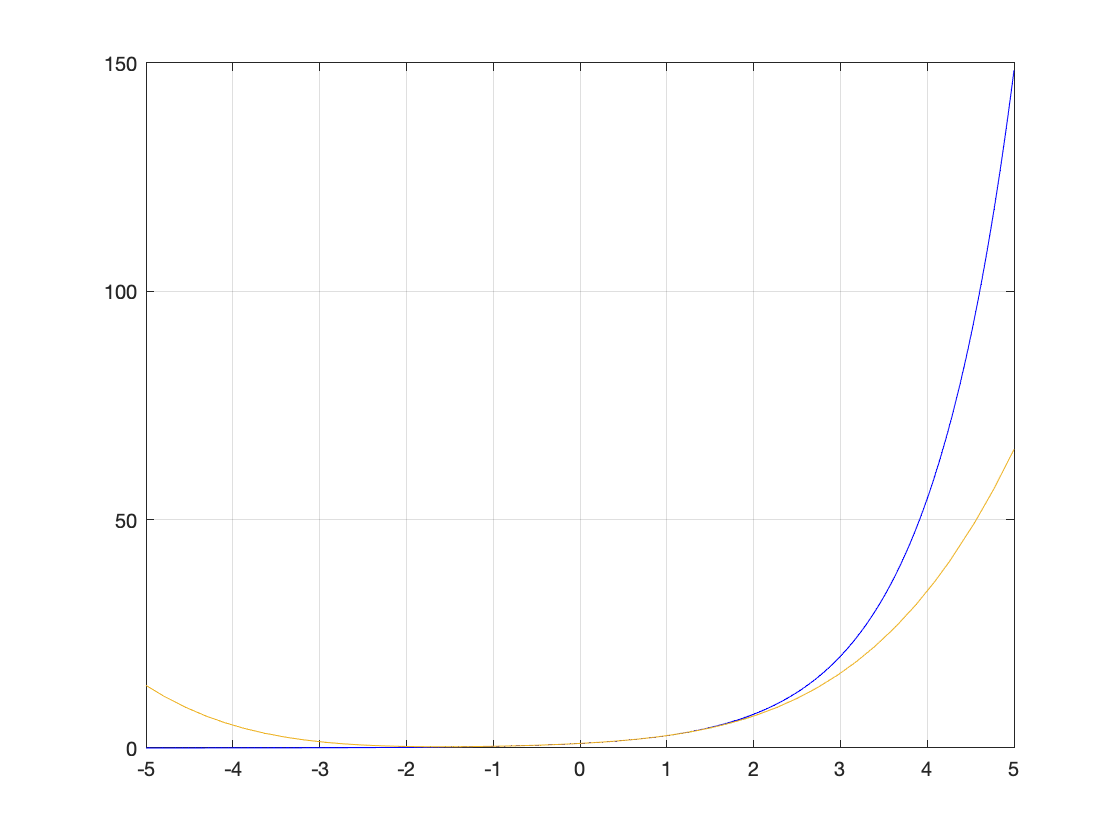





x1 = -5:0.01:5;
y1 = exp(x1);

plot(x1, y1, "Color",'b')
hold on
grid on
fplot(yapr);

7 задание

syms x k b 
y = exp(1/(1-x^2))/(1+x^2)

$$y = \frac{{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{x^{2}+1}$$

ezplot(y, -7,7)
ylabel('f(x)')
grid on
hold on

%%x1 = -10:0.01:10;
k = limit((y/x), inf)

$$k = 0$$

b = limit(y-(k*x), inf)

$$b = 0$$

yasimptota = k*x +b

$$yasimptota = 0$$

ezplot(yasimptota, -7,7)


d= diff(y)

$$d = \frac{2\,x\,{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{{\left(x^{2}-1\right)}^{2}\,\left(x^{2}+1\right)}-\frac{2\,x\,{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{{\left(x^{2}+1\right)}^{2}}$$

xmaxmin = solve(d)

$$xmaxmin = \left(\begin{array}{c} 0\\ \sqrt{3}\\ -\sqrt{3} \end{array}\right)$$

ymaxmin = exp(1/(1-xmaxmin.^2))./(1+xmaxmin.^2)

$$ymaxmin = \left(\begin{array}{ccc} \mathrm{e} & 1 & 1\\ \frac{\mathrm{e}}{4} & \frac{1}{4} & \frac{1}{4}\\ \frac{\mathrm{e}}{4} & \frac{1}{4} & \frac{1}{4} \end{array}\right)$$

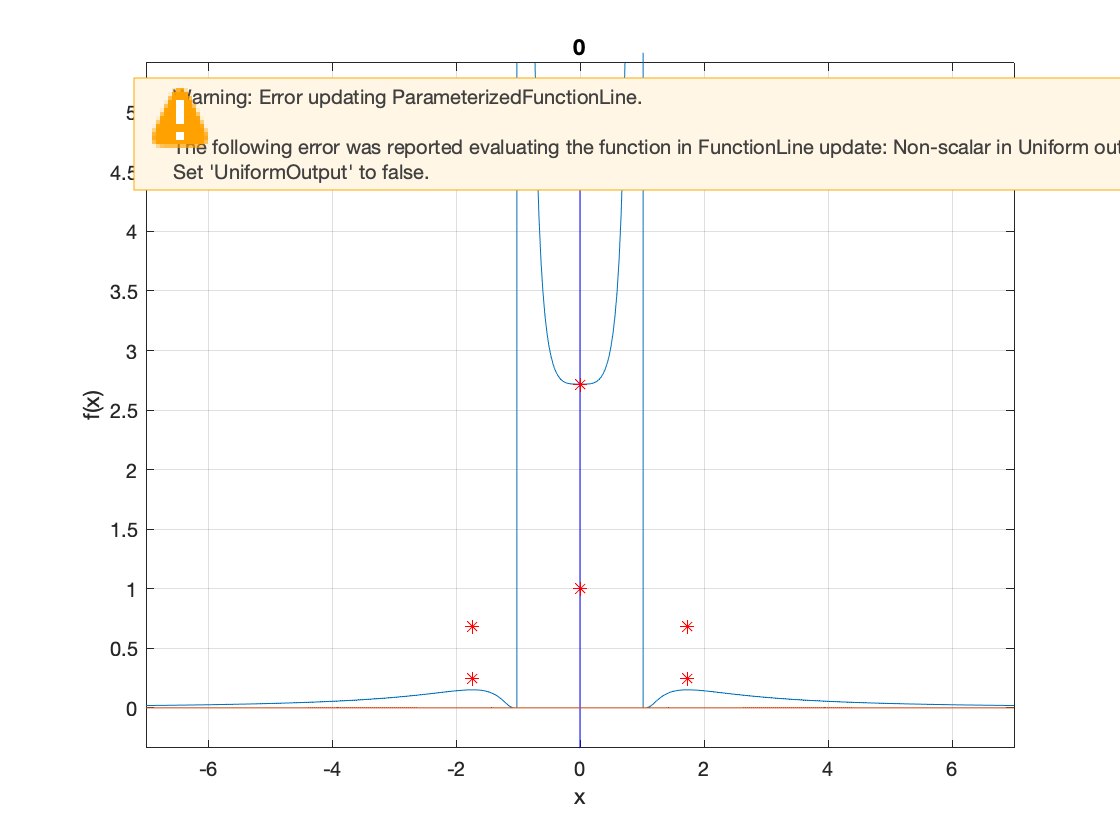

plot(xmaxmin,ymaxmin, "*", "Color",'red');